# Sharp IR Functions

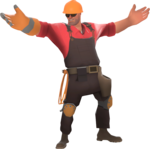

Eliyahu Suskind, 3/3/2023, Revision 1

clc       % clear command window
clear     % clear MATLAB workspace

### Set Up Control System

% Set-up arduino
[robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('COM13');

% Turn board LED on and off to signal program has started
blink(robotArduino, blinkLED, 5);
disp('Warning! Data Collection Active!')

Warning! Data Collection Active!



mymode = input("Enter 0 for data collection mode, 1 for obj detection mode.");

% Create a variable to hold experimental position data
if mymode == 0
nTests = input(['Enter number of range test postions, ' 'followed by enter: ']);
clc 
positionData = zeros(nTests, 2);
end

r = rateControl(0.1);   % create a 0.1 hz loop rate
reset(r);               % reset loop to time zero

### Run Control Loop

% MODE 0: Data Collection
if mymode == 0
controlFlag = 1;                     
while (controlFlag < nTests + 1)

    % Record Data
    rangeData = SENSE(robotArduino, rawRangeIn);

    % Store recorded data
    positionData(controlFlag, 1) = input('Enter distance in mm: ');
    gtest=input('Move sharp to new range, then hit enter ', 's');
    positionData(controlFlag, 2) = rangeData;
    blink(robotArduino, blinkLED, 1);
    waitfor(r);
    controlFlag = controlFlag+1;

end
end

Unrecognized function or variable 'rawRangeIn1'.

Error in SharpIR>SENSE (line 112)
    rangeData = [readVoltage(robotArduino, rawRangeIn), readVoltage(robotArduino, rawRangeIn1)]


% MODE 1: Hole detection
if mymode == 1

% Take baseline reading
fakeVariable = input("Press Enter When Ready to Take Baseline","s");
baselineRange = SENSE(robotArduino, rawRangeIn);

% Detect whether hole or obj exists by comparing baseline with current
% reading. Use acceptable deviation in voltage of 0.005
while true
currRange = SENSE(robotArduino, rawRangeIn);
pause(0.01)
clc
if currRange + 0.03 < baselineRange || currRange - 0.03 > baselineRange
disp("Object Detected.")
else
disp("Hole Detected.")
end
end
end

### Mission data processing

if mymode == 0

% Plot recorded distance in volts vs actual position in mm
plot(positionData(:,1), positionData(:,2), '-*')
xlabel('Actual Position (mm)')
ylabel('Measured Position (v)')
title("Actual Position vs Recorded Position")
grid

end

### Clean and Shutdown

End program by clearing arduino object and command window

clc
disp('Arduino program has ended');
clear robotArduino
beep

### Robot Functions

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% Purpose: configure and create a global arduino object
% Input: COMPORT is COM port of arduino as string
% Output: arduinoCont is arduino obj, myServo is servo obj, LED is LED pin
    
% create global arduino obj
robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');

% configure pin 13 for indicator LED
blinkLED = 'D13';
configurePin(robotArduino, blinkLED, 'DigitalOutput');

% configure A2 pin as analog input for Sharp IRs
rawRangeIn = 'A2';
configurePin(robotArduino, rawRangeIn, 'AnalogInput');

end

function [] = blink(a, LED, n)
% Purpose: blink indicator LED
% Inputs: a is arduino obj, LED is LED pin, n is number of blinks as int

    for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end

end

### Sense Functions

function rangeData = SENSE(robotArduino, rawRangeIn)
% Purpose: Take distance scan with IR sensors.
% Input: robotArduino is the global arduino obj, rawRangIn are the IR
% sensor objects.
% Output: rangeData is the recorded distance reading made.
    rangeData = readVoltage(robotArduino, rawRangeIn), readVoltage(robotArduino, rawRangeIn1);
end